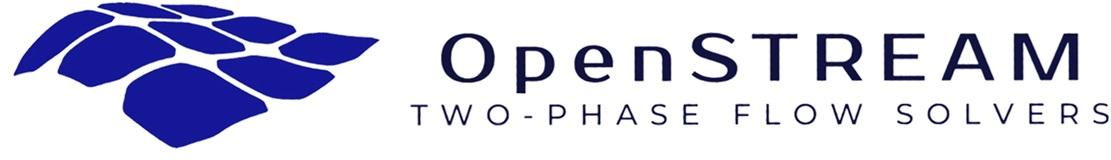

# Tutorial #2: Mixture solver

## Introduction

In this tutorial, you will learn how to use the mixture solver, with examples demonstrating various capabilities.

The geometry consist of a 3.5 m uniformly heated tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section. The flow enters slightly subcooled, transitions to annular two-phase flow around 0.7 m, and reaches film dryout at the end of the heated section. In the adiabatic region, droplets deposit on the wall, regenerating the liquid film at the wall and leading to a fully developed annular flow.

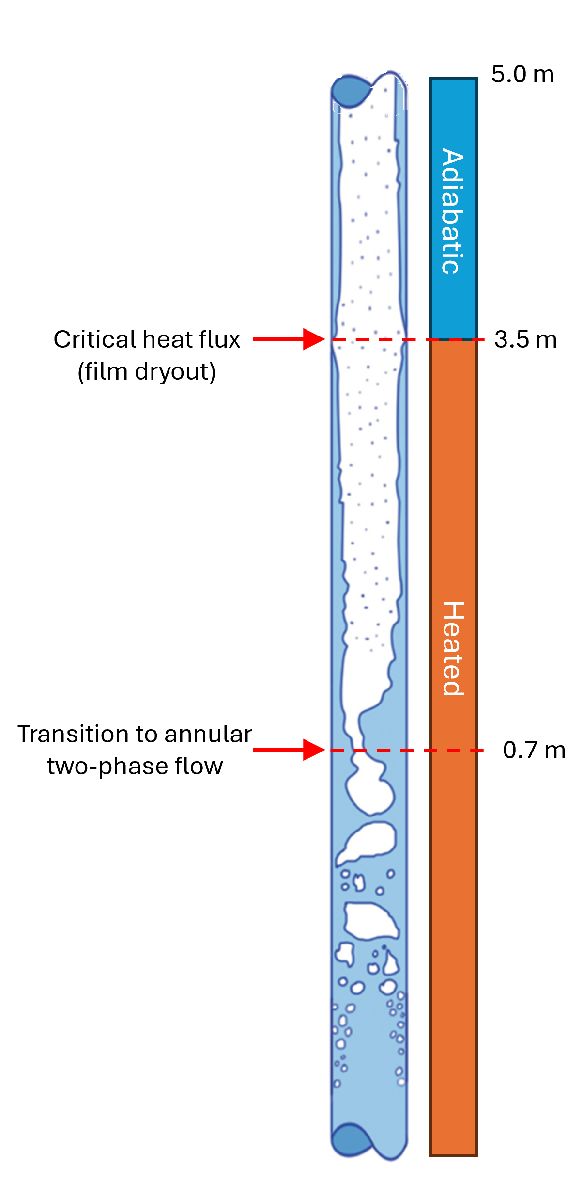

Before starting this tutorial, make sure OpenSTREAM is included in your MATLAB search path. If you are running the tutorial directly from the `tutorials` folder, you can add OpenSTREAM like this:

osp = './..';
addpath(osp);

## Input files

All the input files you will need for this tutorial are already provided in the `openstream/inputs/` folder.

We first start by adding the inputs and solver classes to the import list. 

% Import the necessary classes for inputs and solvers
import Inputs.*
import Solvers.*

We then add the mixture solver classes to the import list. 

% Import the mixture solver class
import Solvers.Mixture.*

We can examine the physical model inputs by opening the models file or using the command below, then scroll to locate the entry labeled `TUTORIAL2*`.

type('../inputs/models.inp')

This indicates that the simulations will use 100 nodes and that water is the working fluid. Models not specificed are set to their default values by the code. That is:

- `TUTORIAL2A` does not specified any model, hence an homogeneous equilibrium model (HEM) is assumed.

- `TUTORIAL2B` selects a slip void model with a slip ratio of 2

- `TUTORIAL2C` selects a drift flux model (BESTION)

We can examine the numerical option inputs by opening the options file or using the command below, then scroll to locate the entry labeled `DEFAULT`.

type('../inputs/options.inp')

Note that no specific options have been defined, i.e., defaults setting are used for the simulations.

We can examine the geometry inputs by opening the geometry file or using the command below, then scroll to locate the entry labeled `TUTORIAL1`.

type('../inputs/geom.inp')

All inputs are specified in SI units and required except for `ANGLE`, which defaults to 0, indicating a vertical test section. The separate specification of `AREA` and `PERIM` allows to define test sections of arbitrary shape. In this case, the area and perimeter corresponding to a circular test section with a diameter 8.8 mm were specified.

Finally, we can examine the boundary conditions by opening the boundary conditions file or using the command below.

type('../inputs/bc_tutorial1.inp')

Defining a single time step indicates that the simulation is steady-state. The axial power distribution is specified using two arrays: `WMESH` for node size and `WPOWER` for corresponding wall heat flux. In this case, the configuration represents a 3.5 m uniformly heated section followed by a 2 m adiabatic section.

All inputs are specified in SI units and required except for `WMESH` and `WPOWER`. If they are omitted, the test section is assumed to be uniformly heated by default.

## Homogeneous Equilibrium Model (HEM)

In this section, we will walk through how to set up and run the mixture solver using the simplest set of physical models available.

By default, the physical models in the mixture solver are consistent with the Homogeneous Equilibrium Model (HEM). That is, hydrodynamic and thermal equilibrium is assumed along with no slip between the phases.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. Since each file can include various set of inputs (several geometries, etc.), the IDs corresponding to the relevant sets must be indicated. These paths can be modified by the user, based on the specific working directory and file locations.

The models and options parameters not specified in the input files are set to their default values. Turning on the warning will print the corresponding models and options values to the prompt. 

% Turn off warnings during input setup
%warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2A', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/bc_tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
%warning on

Note that `LOGMODE` can be set to `'LOGTOFILEONLY'` to suppress (almost) all print outputs when running OpenSTREAM.

The mixture solver object, `mixSolver`, is created from the `inputSet`.

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

The mixture solver class includes built-in plotting functions to help visualize the results. Not indicating any argument (`mixSolver.plotz()`) will generates figures for most relevant parameters. Various name-value arguments are available, such as `display` to select the parameter(s) to be plotted.

We start by plotting the axial distribution of wall heat flux along the test section.

% Plot the axial distribution of heat flux
mixSolver.plotz('display','HFLUX');

The wall heat flux is imposed by the `WMESH` and `WPOWER` inputs in the boundary conditions input file. Here we verify that uniform power is applied along the first 3.5 m, followed by a 2 m long adiabatic region.

We can then plot the axial distributions of mixture and phase mass flow rates.

% Plot the axial distribution of mass flow rates
mixSolver.plotz('display','W');

Vapor generation begins near the inlet of the test section as the mixture reaches saturation. From there, vapor mass increases  linearly along the heated length due to the uniform heat flux, and then remains constant throughout the adiabatic section. This behavior is typical of HEM simulation results.

Finally, we plot the axial distributions of vapor volumetic (void) and mass (quality) ratios.

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

The figure confirms that the mixture becomes saturated (xeq ≥ 0) as the steam mass (and void fraction) starts increasing.  This behavior is typical of HEM simulation results.

% Save the solver object
mixSolver.save()

The solver object can be retrieved later by using the `load` command.

## Non-homogeneous models

In this section, two non-homogeneous models are demonstrated where the phases have different velocities. This is achieved by calculating the void fraction based either on the slip void model or the drift flux void model, instead of the homogeneous void model.

### Slip void model

In this section, we will walk through how to set up and run the mixture solver using a simple slip void model.

The only difference with the previous case is that input `VOID` is set to `SLIP` and input `SLIP` is set to `2` in the models file.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models ID corresponding to the void slip model (`TUTORIAL2B`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2B', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/bc_tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, mixSolver, is created from the inputSet.

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetic (void) and mass (quality) ratios.

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

While the quality is the same as in the previous simulation (thermodynamic equilibrium assumption), the void is slighly lower, charateristic of a velocity slip between the vapor and liquid phases.

This is verified by plotting the axial distributions of phase velocity.

% Plot the axial distribution of phase velocities
mixSolver.plotz('display','U');

The calculated vapor velocity is observed to be twice higher than the liquid velocity, as specified by the `SLIP` void model.

### Drift flux void model

In this section, we will walk through how to set up and run the mixture solver using a drift flux void model.

The only difference with the previous case is that input `VOID` is set to `BESTION`. This model is one of several drift flux void model available, which has the merit to be simple and accurate for many applications.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by InputSet. The models ID corresponding to the void slip model (`TUTORIAL2C`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2C', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/bc_tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, mixSolver, is created from the inputSet.

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetic (void) and mass (quality) ratios.

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

While the quality is the same as in the previous simulation (thermodynamic equilibrium assumption), the void is slighly different due to different and varying velocity differences between the phase along the channel..

This is verified by plotting the axial distributions of phase velocity.

% Plot the axial distribution of phase velocities
mixSolver.plotz('display','U');

The calculated vapor velocity is observed to be higher than the liquid velocity (though with a slip ratio less than 2), as specified by the `BESTION` void model.

## Non-thermal equilibrium models

In this section, two non-thermal equilibrium models are demonstrated where the phases have different temperatures. This is achieved by calculating the vapor mass quality based either on tan empirical model or a physical model representative of interfacial mass and heat transfer, instead of the thermal equilibrium assumption.

### Empirical model

In this section, we will walk through how to set up and run the mixture solver using an empirical subcooled boiling model.

The only difference with the previous case is that input `THERMALNONEQ` is set to `SAHAZUBER` in the models file.

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models ID corresponding to the void slip model (`TUTORIAL2D`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2D', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/bc_tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, mixSolver, is created from the inputSet.

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

The vapor mass quality begins to increase near the inlet, even though the equilibrium thermodynamic quality remains negative. Consequently, the void fraction also increases in that region. This behavior is characteristic of subcooled boiling, as captured by the model.

### Homogeneous Relaxation Model (HRM)

In this section, we will walk through how to set up and run the mixture solver using a physical subcooled boiling model.

The only difference with the previous case is that input `THERMALNONEQ` is set to `RELAXATION` in the models file. This model is based on two additional conservation equations for the vapor phase (mass and energy) allowing to physically describe non-thermal equilibrium exchanges across the interface. 

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet`. The models ID corresponding to the void slip model (`TUTORIAL2E`) is indicated.

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
    modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL2E', ...
    optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
    geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
    bcFilePath            = [osp '/inputs/bc_tutorial1.inp'], ...
    sessionParentDir      = fullfile(pwd,'outputs')    , ...
    overwriteSessionFiles = true                       , ...
    LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

The mixture solver object, mixSolver, is created from the inputSet.

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If convergence is reached, it prints a summary of the time step convergence.

We plot the axial distributions of vapor volumetric (void) and mass (quality) ratios.

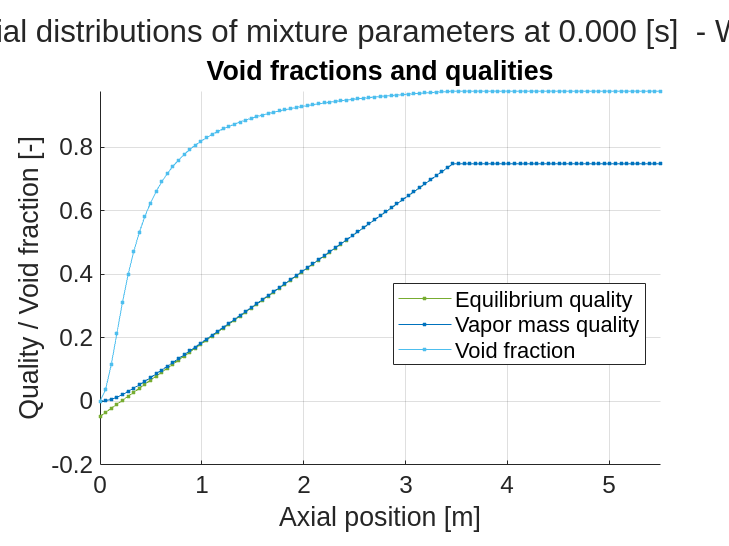

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

The vapor mass quality begins to increase near the inlet, even though the equilibrium thermodynamic quality remains negative. Consequently, the void fraction also increases in that region. This behavior is characteristic of subcooled boiling, as captured by the model.

A future tutorial will describe in details the features and capabilities of the Homogeneous Relaxation Model.

## Pressure drop models

### Wall friction

### Singular pressure loss